# Finding a 2D SSM from sloshing data

This is an example of how a slow 2D SSM can be fitted to experiment data to predict the system's forced response. This example uses measurements of the center of mass displacement of the liquid in a horizontally excited sloshing tank [1].

clearvars
close all
clc

[1] B. Bäuerlein and K. Avila, Phase-lag predicts nonlinear response maxima in liquid-sloshing experiments, *Journal of Fluid Mechanics* 925 (2021) A22.

## Example setup

The data consists of three decaying center of mass signals, along with data points of the forced response at three forcing amplitudes. SSMLearn is trained only on the decaying data and predicts a forced response that agrees well with the data points from the forced system. The experiment setup is shown below [1]. 

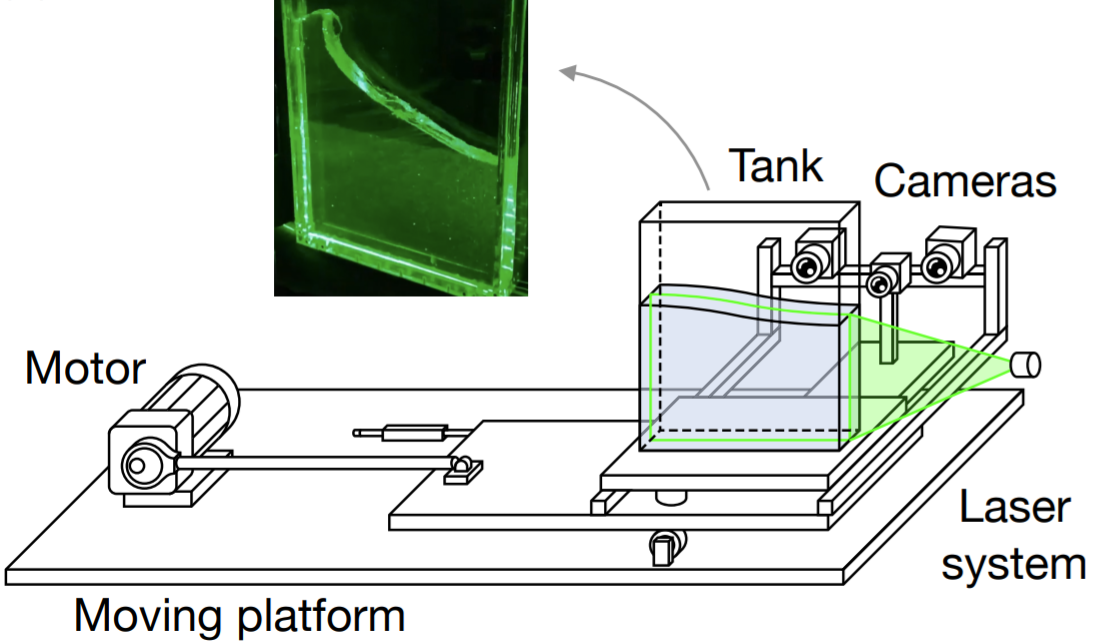

The training trajectories were measured by exciting the tank and then detaching the motor, at three different frequencies, allowing free resonance decay. The data is assumed to lie close to the slowest 2D SSM.

datadir = 'data/';
frcExp{1} = load([datadir,'Measurements_A=0.09%.txt']);
frcExp{2} = load([datadir,'Measurements_A=0.17%.txt']);
frcExp{3} = load([datadir,'Measurements_A=0.32%.txt']);
amplitudes = [0.09, 0.17, 0.32];

load ([datadir, 'xData']);
decayFrequencies = [0.953 0.960 0.967];
for iFreq = 1:length(decayFrequencies)
    titles{iFreq} = ['$\Omega = ', num2str(decayFrequencies(iFreq)), '$'];
end
indTrain = [2 3];
indTest = [1];

## Delay embedding

Now we arrange the scalar measurements in an observable space of dimension at least $2m+1$, with $m$ the dimension of the manifold. This guarantees that the manifold from the full state space can be embedded in the observable space.

We form a multi-dimensional observable by stacking $d$ subsequent scalar measurements $x$ in a vector $y$, and we will later use the trajectories in this augmented space for the manifold fitting.


$$\left[\begin{array}{c}y_{1} \\ \vdots \\ y_{i+1} \\ \vdots \\ y_{d+1}\end{array} 
\right] = \left[\begin{array}{c}x(t^k) \\ \vdots \\ x(t^k+i\Delta t) \\ \vdots 
\\ x(t^k+d\Delta t)\end{array} \right]$$


The total number of embedded coordinates is $2m+1 + \texttt{overEmbed}$.

SSMDim = 2;
overEmbed = 0;
[yData, opts_embd] = coordinatesEmbedding(xData, SSMDim, 'OverEmbedding', overEmbed);

The 5 embedding coordinates consist of the measured state and its 4 time-delayed measurements.


embedDim = size(yData{1,2},1);
outdof = floor(embedDim/2)+1;

## Data filtering

We need to make sure that the data that we use to identify the slow attracting manifold lies close to it. This may not be the case for the very first transient data, as the time series starts at motor detachment. Therefore, we remove some of the initial data. 

sliceInt = [1.0, Inf];
yDataTrunc = sliceTrajectories(yData, sliceInt);

## Manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace $V_e$. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

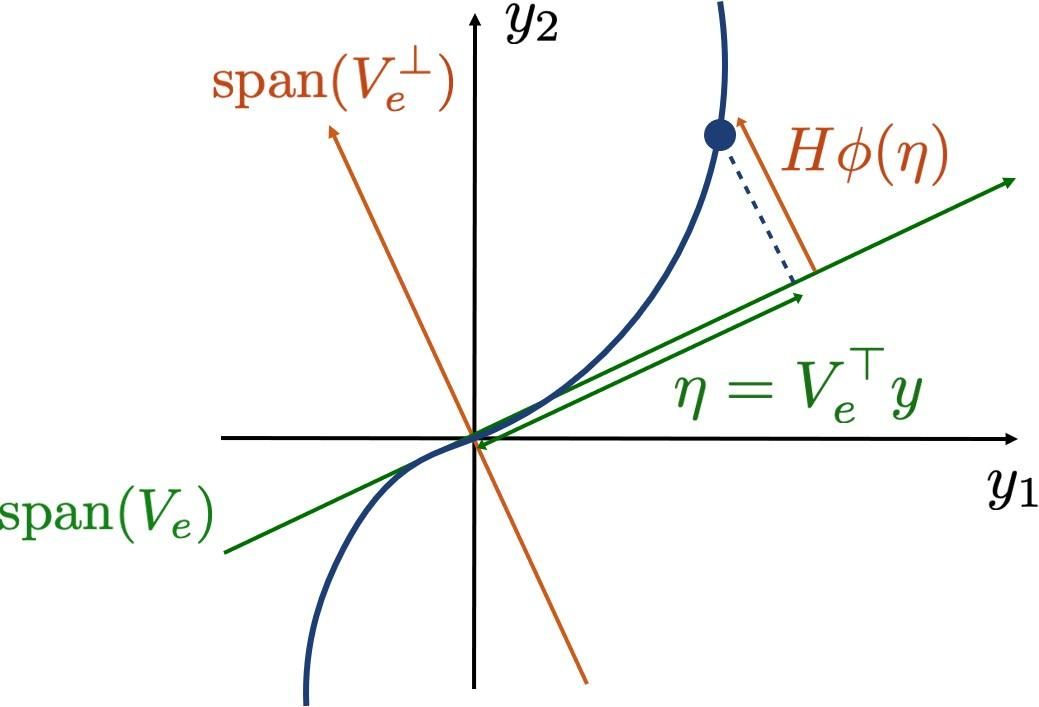

We seek the $2n\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y)$,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem is formulated as the minimization of a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top 
y_k) ||$$


to find $H$ and the $2n\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMGeometry`.

SSMOrder = 1;
IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);

## Plot and validation

Now that we have computed the tangent space of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto it:

$\eta = V_e^\top y$.

etaDataTrunc = projectTrajectories(IMInfo, yDataTrunc);

We plot the manifold and the trajectories in the reduced coordinates.

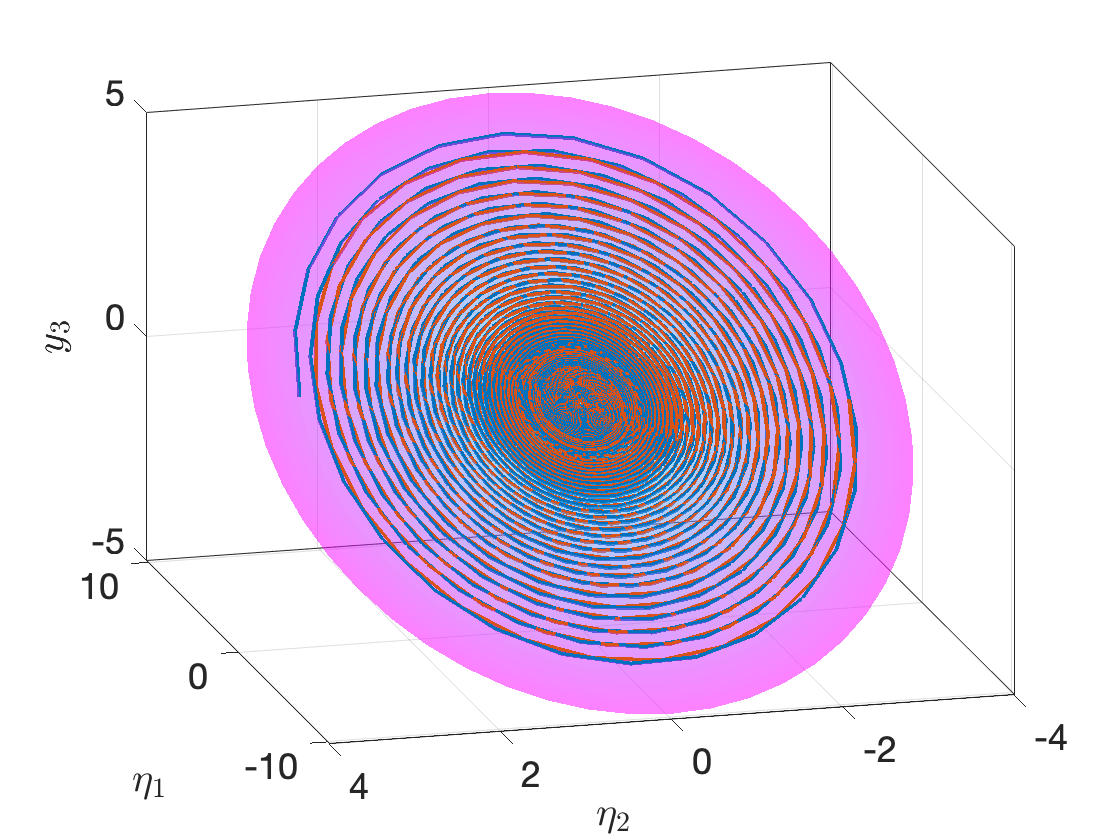

plotSSMWithTrajectories(IMInfo, outdof, yDataTrunc(indTrain,:));
view(-105,23)

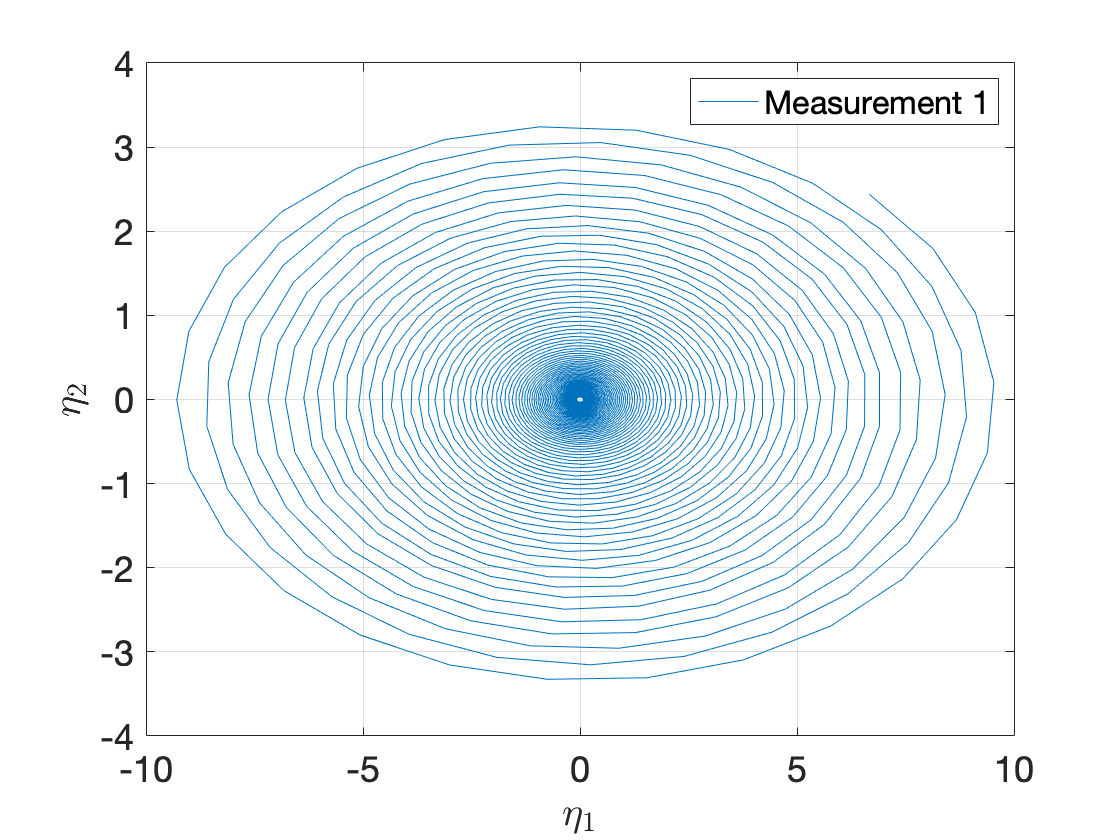

plotReducedCoordinates(etaDataTrunc(indTest(1),:));

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsFlow` fits a polynomial map


$$\dot{\eta} = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics on a normal form, and seek the Taylor expansion of a map $N$ fulfilling


$$\dot{z} = N(z) =Dz + W_n\phi(z)$$


with $D$ a diagonal matrix and $W_n$ containing coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(\eta) = \eta + W_t \phi(\eta)$$


with $W_t$ containing the coefficients for the nonlinear terms of the coordinate change.

Estimation of the reduced dynamics...  Done. 
Estimation of the reduced dynamics in normal form...
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           1       0.00297463                        0.0311
     1           2       0.00204773              1         0.0258  
     2           4       0.00103728       0.440067         0.0476  
     3           6      0.000215077       0.168288         0.0131  
     4           8      8.80493e-05       0.341989       0.000363  
     5           9       8.7828e-05              1       0.000395  
     6          11      8.78035e-05        0.10994       0.000128  
     7          12      8.77611e-05              1       3.12e-05  
     8          13      8.77542e-05              1       3.11e-05  
     9          14      8.77435e-05              1       3.68e-05  
    10          15      8.77167e-05              1       7.67e-05  
    11          16

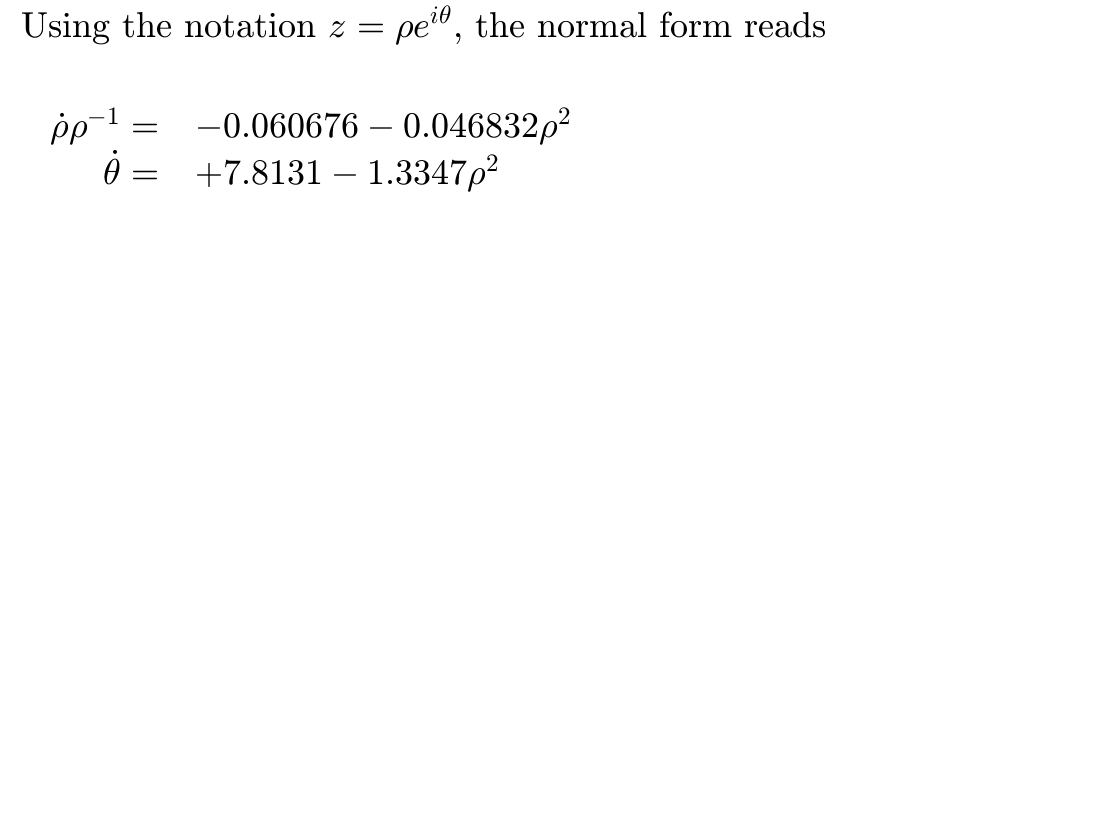

ROMOrder = 3;
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), ...
    'R_PolyOrd', ROMOrder, 'style', 'normalform');

We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and integrate our reduced order evolution rule to predict the development of the trajectory. 

[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yDataTrunc);

## Evaluation

The normalized mean trajectory error NMTE is computed as the average distance of the predicted trajectory to the measured one in the observable space, normalized by the observable vector with maximum norm in the data. 

fullTrajDist = computeTrajectoryErrors(yRec, yDataTrunc);
NMTE = mean(fullTrajDist(indTest))

NMTE = 0.0160

We plot the measured and predicted center of mass signal for the test trajectory. The reduced model seems to do well on previously unseen data.

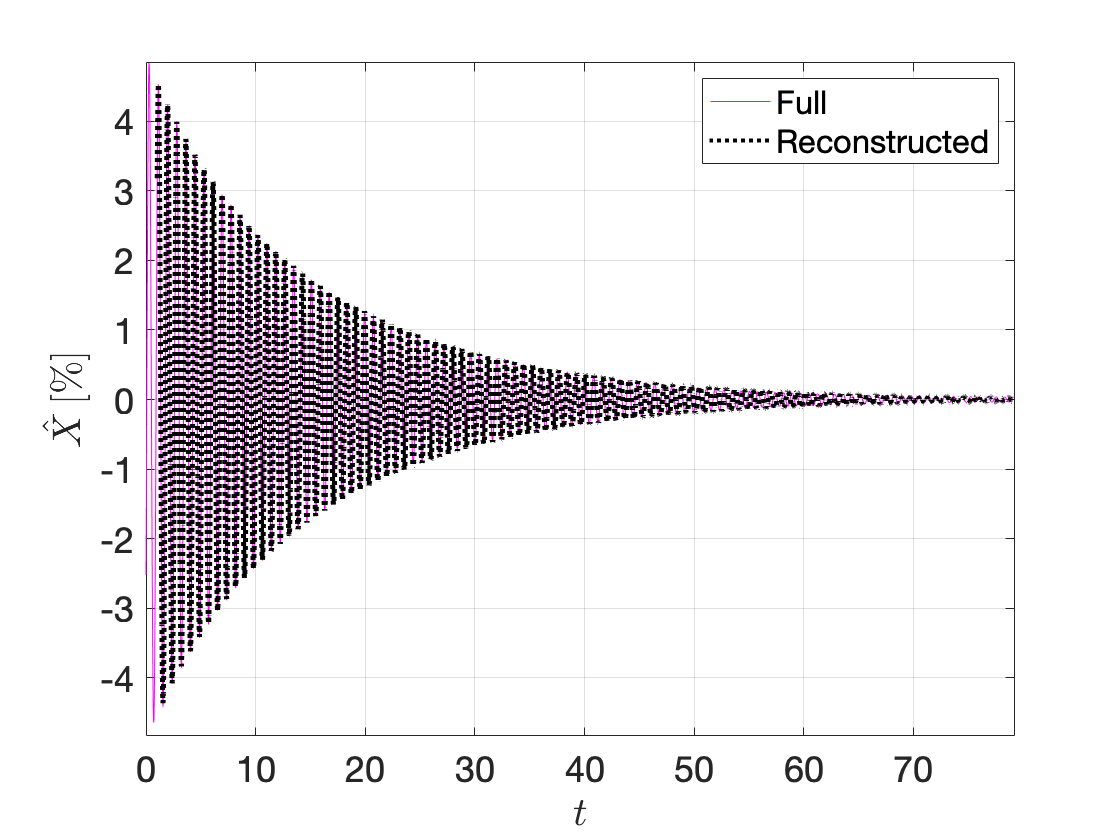

plotTrajectories(yData(indTest,:), yRec(indTest,:), 'm', outdof, 'Title', titles)
ylabel('$\hat{X} \, [\%]$','Interpreter','latex'); title('');

## Backbone curves

With the knowledge of the coefficients of the normal form, we extract backbone curves for the instantaneous damping and frequency.

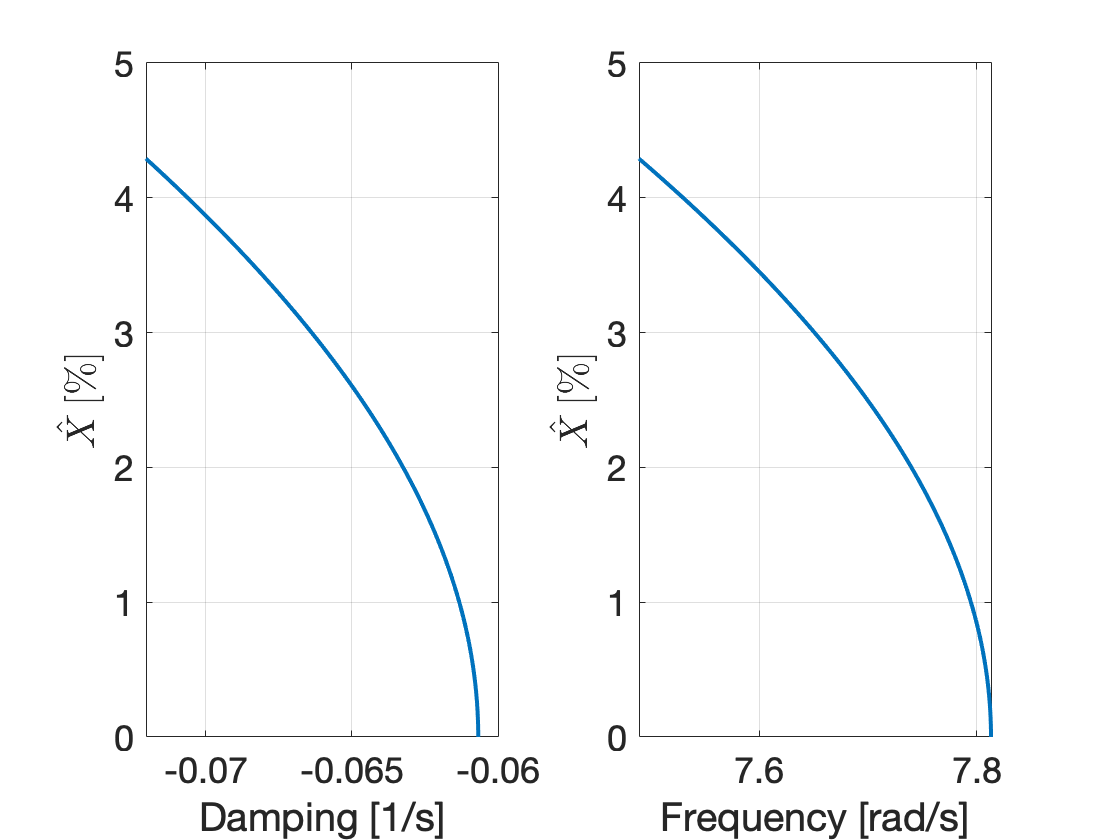

yObservable = @(y) y(outdof,:);
rhoMax = max(abs(zRec{indTrain(1),2}(1,:)));
BBCInfo = backboneCurves(IMInfo, RDInfo, yObservable, rhoMax);
subplot(121); ylabel('$\hat{X} \, [\%]$','Interpreter','latex')
subplot(122); ylabel('$\hat{X} \, [\%]$','Interpreter','latex')

## Compute forced response curves

The data-driven model trained on autonomous data can now be used for forced response predictions. With the addition of forcing, the normal form dynamics becomes 

$$\dot{z} =N(z) + f_{red} e^{i\Omega t}$,

where $$\Omega$ is the forcing frequency and $$f_{red}$ is the forcing amplitude. For FRC extraction, we analytically compute fixed points of the polar normal form via a closed form solution.

We need to define the forcing amplitude in the normal form. We do this by passing to `calibrateFRC` a frequency and a point $y_\mathrm{cal}$ in the observable space. At the defined frequency, the calibrated FRC will reach the amplitude of this point. 

The vector $y_\mathrm{cal}$ lies in a delay embedded space, and can be computed either from a delay embedded time-varying response signal, or from a scalar maximal response that is artifically delay embedded. For a scalar value $u_\mathrm{cal}$, this can be achieved by projection onto the tangent space. This method only works for a limited delay embedding dimension. We use the maximal amplitude data point at each forcing level for calibration.

clear yCal
w_span = [0.87, 1.06]*7.8;
V = IMInfo.parametrization.tangentSpaceAtOrigin;
[~,maxmode] = max(abs(V(outdof,:)));
for iAmp = 1:length(amplitudes)
    [uCal, pos] = max(frcExp{iAmp}(:,2));
    Omega(iAmp) = frcExp{iAmp}(pos,1)*7.8;
    yCal(:,iAmp) = uCal*V(:,maxmode)./V(outdof,maxmode);
end
fRed = calibrateFRC(IMInfo, RDInfo, yCal, Omega);

[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1);

Forced SSM reduced-order model assumes external forcing only along the tangent (modal) subspace at the origin. 


FRC = analyticalFRCf(IMInfoF, RDInfoF, fRed, yObservable);
for iAmp = 1:length(amplitudes)
    FRC.(['F',num2str(iAmp)]).Nf_Phs = -180*(max(max(FRC.(['F',num2str(iAmp)]).Nf_Phs))>0)+...
        180/pi*FRC.(['F',num2str(iAmp)]).Nf_Phs;
end

## Plot FRCs

Comparison of the FRCs from SSMLearn with experimental data shows that our autonomous model also predicts the response of the forced system well at these amplitudes, both in terms of amplitude and phase lag.

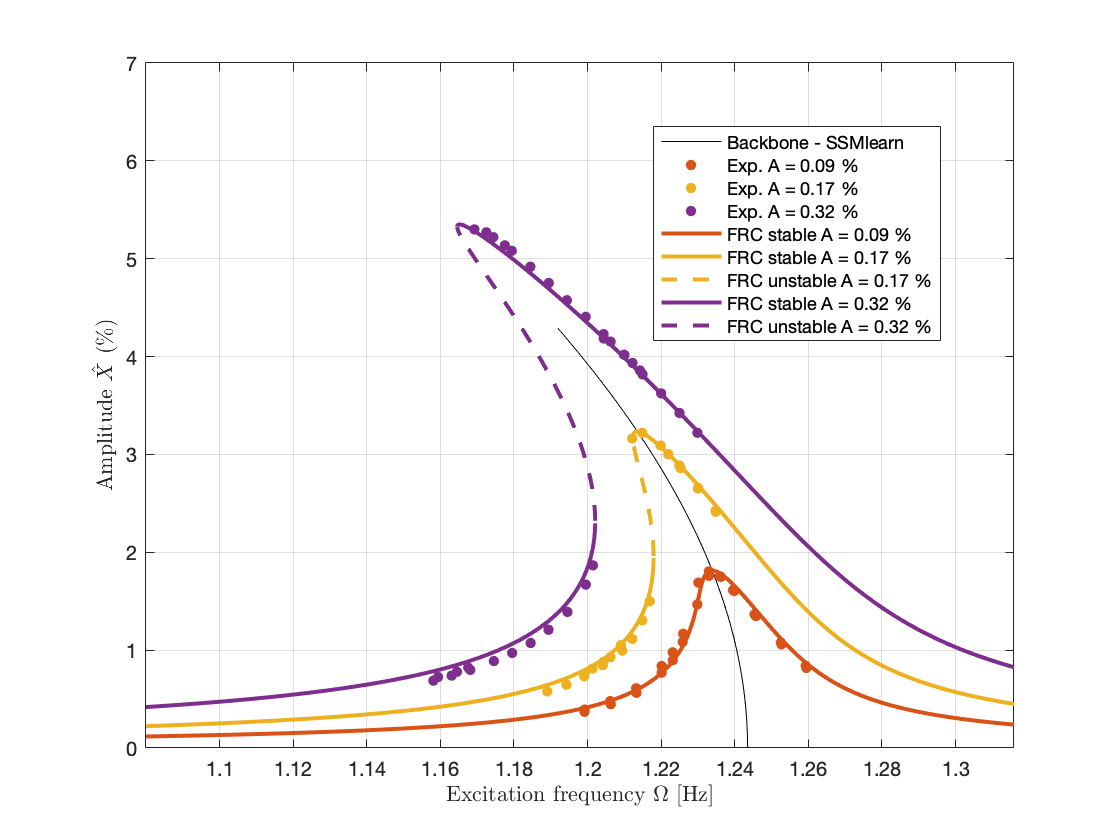

figure(100); hold on; colors = colororder; colors = colors(2:end,:);
plot(BBCInfo.frequency/2/pi, BBCInfo.amplitude,'k','DisplayName', 'Backbone - SSMlearn')
figure(101); hold on;
for iAmp = 1:length(amplitudes)
    labels{iAmp} = ['A = ', num2str(amplitudes(iAmp)), ' %'];
    figure(100);
    plot(frcExp{iAmp}(:,1)*7.8/2/pi, frcExp{iAmp}(:,2), '.', 'MarkerSize', 12, ...
        'Color', colors(iAmp,:), 'DisplayName', ['Exp. A = ', num2str(amplitudes(iAmp)), ' %'],...
        'MarkerSize', 14)
    figure(101);
    plot(frcExp{iAmp}(:,1)*7.8/2/pi, frcExp{iAmp}(:,3), '.', 'MarkerSize', 12, ...
        'Color', colors(iAmp,:), 'DisplayName', ['Exp. A = ', num2str(amplitudes(iAmp)), ' %'])
end
figure(100)
plotFRC(FRC, colors, labels, 'freqscale', 2*pi)
xlim(w_span/2/pi)
ylim([0,7]);
xlabel('Excitation frequency $\Omega$ [Hz]', 'Interpreter', 'latex')
ylabel('Amplitude $\hat{X}$ (\%)', 'Interpreter', 'latex')

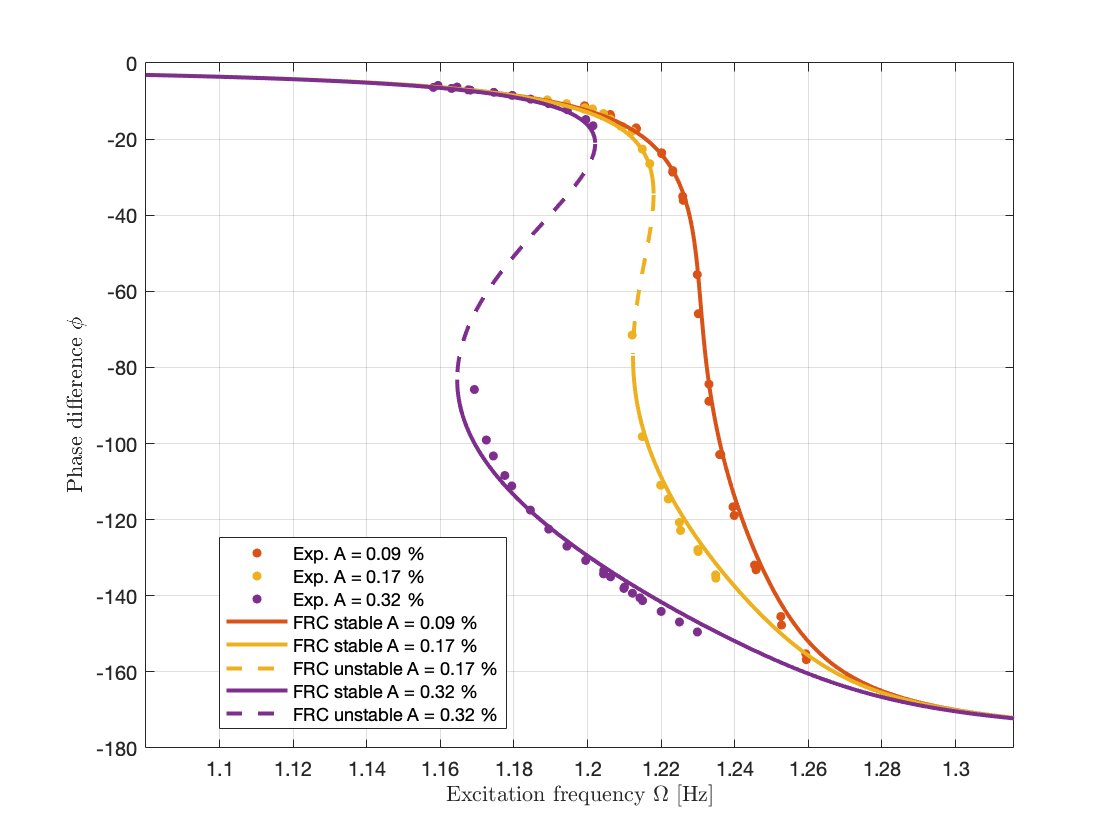

figure(101)
plotFRC(FRC, colors, labels, 'y', 'Phase', 'freqscale', 2*pi)
xlim(w_span/2/pi)
ylim([-180,0]);
xlabel('Excitation frequency $\Omega$ [Hz]', 'Interpreter', 'latex')
ylabel('Phase difference $\phi$', 'Interpreter', 'latex')